lambda = 1e-5:0.1:5; % Range of lambdas
energies = arrayfun(@getE, lambda); % Compute E(lambda) at all values

% Compute E(lambda) at a specific point
lambdadisplay = 0.5;
disp(['For lambda = ',num2str(lambdadisplay),', E/E_inf = ',num2str(getE(lambdadisplay))])

For lambda = 0.5, E/E_inf = -1.6345


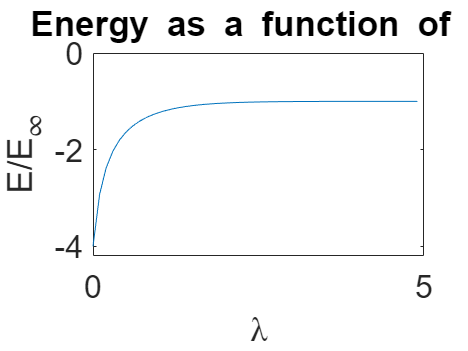


% Create the plot
p=plot(lambda,energies);
p.Parent.FontSize = 16;
title('Energy as a function of \lambda');
xlabel('\lambda');
ylabel('E/E_{\infty}');
axis([0,5,-4.2,0]);


% Function to compute the energy at a given lambda

function val = getE(lambda)
    % Perform a root finding operation to obtain the value of xi(lambda)
    xi = fzero(@(xi) f(xi,lambda),0.5);
    % Return the energy E/E_inf
    % You have variables xi and lambda available to use
    val = -xi^2/lambda^2;
end

% Function that we want to find the root of
function val = f(xi,lambda)
    val = xi/(1+exp(-2*xi))-lambda;
end
